clear all

nrep = 1000;
row_tot_sd = zeros(1, nrep);
sd_vec = zeros(1,9)

sd_vec =      0     0     0     0     0     0     0     0     0


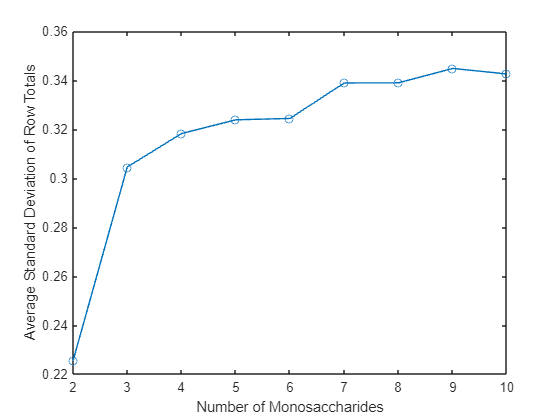


for l = 2:10
    for k = 1:nrep
        nspec = 10;
        nm = l;
        np = 10;
        p_length = 100;
        
        polys = zeros(np, nm);
        for i = 1:np
            polys(i, :) = create_poly(p_length, nm);
        end
        
        cons_traits_mono = rand(nspec, nm);
        cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2);
        
        C = zeros(nspec, np);
        for i = 1:nspec
            C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
        end
        C = (C * nm) / 50;
        row_tot_sd(k) = std(sum(C,2));
    end
    sd_vec(l-1) = mean(row_tot_sd);
end

plot(2:10, sd_vec, '-o')
xlabel('Number of Monosaccharides');
ylabel('Average Standard Deviation of Row Totals');

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end